# HW 4 Dominic Riccoboni

## Radiation Constants

h = 6.62607015e-34; %[Js] Planck's constant
KB = 1.380649e-23; %[J/K] Boltzmann constant
C0 = 2.9979e8; %[m/s] Speed of light in vacuum
C1 = h*C0^2 %[Jm^2/s]

C1 = 5.9551e-17

C2 = h*C0/KB; %[m*K]

## Problem 2.4

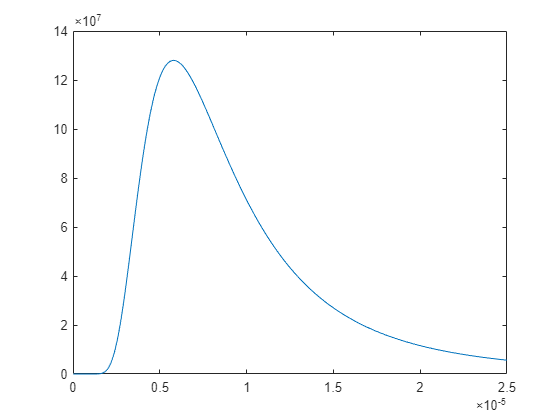

lambdaTguess = 3000*10-6; %[mK]

E_lam_b_fun = @(lambda,T) 2*C1./lambda.^5./(exp(C2./(lambda.*T))-1);

n = 1000;

lambdas = linspace(0, 25e-6, n);

T1 = 500; %500 [K]

E_lam_b1 = E_lam_b_fun(lambdas,T1*ones(size(lambdas)));



i_lambda1 = lambdas(lambdas <= 1.95e-6);
i_lambda2 = lambdas((1.95e-6 < lambdas) & (lambdas <= 4.75e-6));
i_lambda3 = lambdas(4.75e-6 < lambdas);

emsvty_lam = [0.3*ones(size(i_lambda1)), 0.8*ones(size(i_lambda2)), 0.5*ones(size(i_lambda3))];


plot(lambdas, E_lam_b1)